## Plot Path

load map.mat;
mode = "Nominal";

f1 = figure(1); clf;
hold on;
show(map);
plot(pos_observed.Data(1,1), pos_observed.Data(1,2), 'go', 'markerfacecolor', 'g', 'markersize', 8, "DisplayName", "start");
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'bo', 'LineWidth', 3, "DisplayName", "waypoint"); 
end
%plot(pos_actual.Data(:,1), pos_actual.Data(:,2), 'linewidth', 6);
plot(pos_observed.Data(:,1), pos_observed.Data(:,2), 'm', 'linewidth', 3, "DisplayName", "actual");
if ~any(stop_code.Data(:,3))
    plot(pos_observed.Data(end, 1), pos_observed.Data(end, 2), 'rx', 'markersize', 9, 'LineWidth', 3, "DisplayName", "crash");
end
plot(trajectory.x_ref_points(:,2), trajectory.y_ref_points(:,2), 'g--', 'linewidth', 2, "DisplayName", "reference");
hold off;
title("UAV Path and Waypoints");
legend;

## Euclidean Position Error

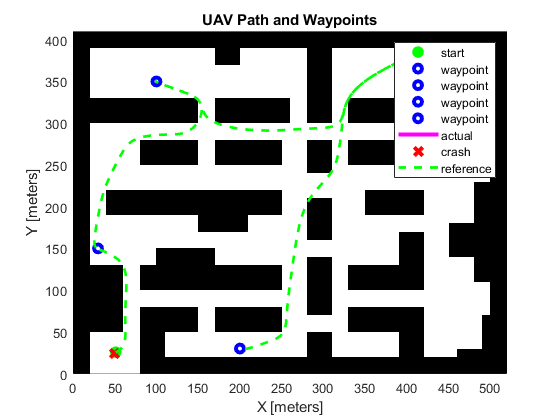

f2 = figure(2); clf;
plot(euclidean_pos_err);

ttl = sprintf("%s - %s - %s", 'Euclidean Position Error', sys, mode);
title(ttl);

## Voltage and SOC Plot

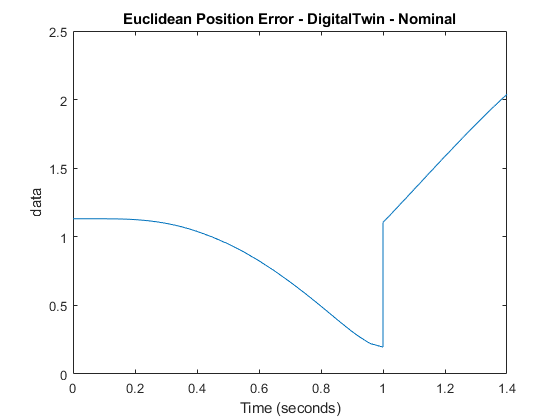

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;

hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'b.',  "DisplayName", "Sampled Voltage");
plot(battery_observed.Time(:), battery_observed.Data(:,2), 'm', 'linewidth', 3, "DisplayName", "estimated Voltage");
plot(battery_actual.Time(:), battery_actual.Data(:,1), 'g', 'linewidth', 3, "DisplayName", "actual Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
if sys == "TrueSystem"
    plot(battery_observed.Time(:), battery_observed.Data(:,3), '--', "DisplayName", "Estimated SOC");
end

plot(battery_actual.Time(:), battery_actual.Data(:,2),'-', 'linewidth', 2, "DisplayName", "Actual SOC");
hold off;
ttl = sprintf("%s - %s - %s", 'Voltage and SOC plot', sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

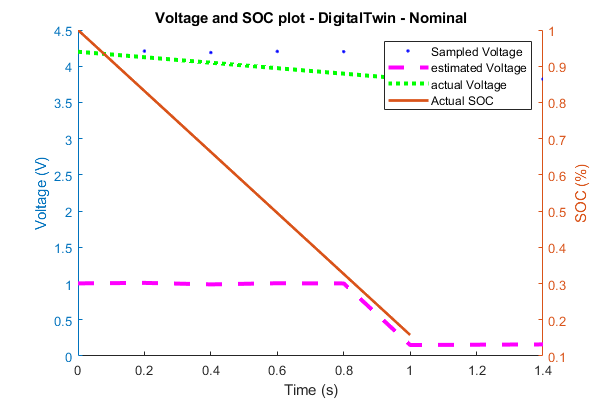

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(current.Time(:,1), current.Data(:,1), 'b', 'linewidth', 1, "DisplayName", "Actual Current");

plot(downsample(current.Time(:,1), 3),smoothdata(downsample(current.Data(:,1), 3), 'rlowess', 20), 'linewidth', 2, "DisplayName", "Average Current");
hold off;
title(sprintf("%s - %s - %s", 'Current Demand', sys, mode));
xlabel("Time (s)");
ylabel("Current (A)");
ylim([15 40]);
legend();